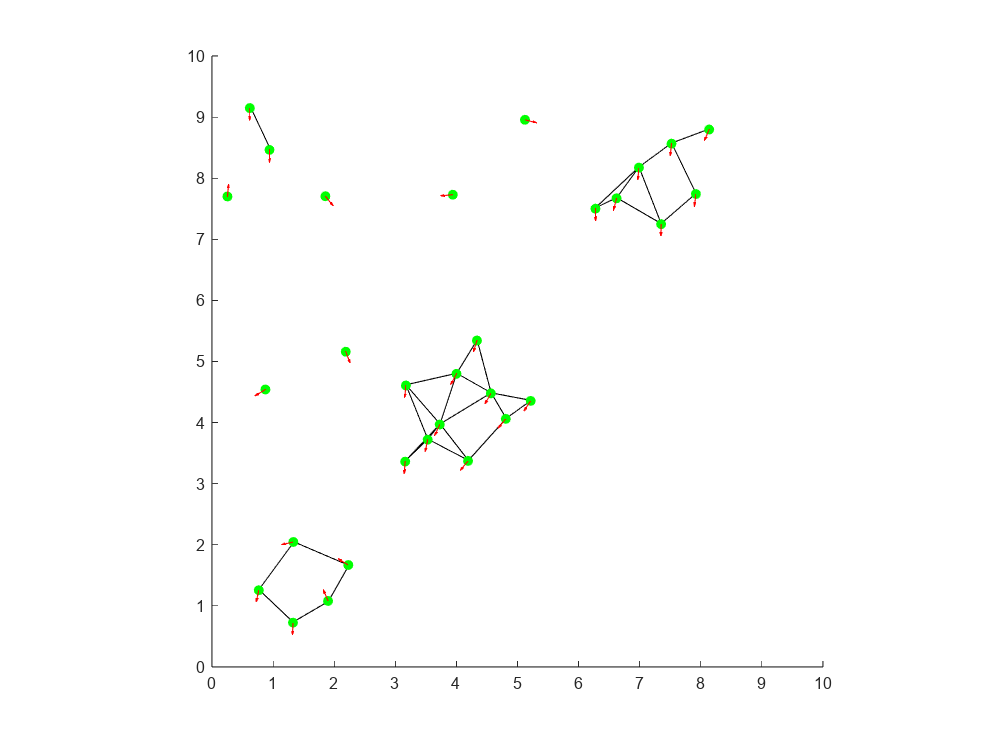

% Initialize the boids' positions and velocities
num_boids = 30;
boids_size = 20;
positions = 10.*rand(num_boids, 2); % Random positions between [0, 1]
velocities = 10.*rand(num_boids, 2) - 5; % Random velocities between [-0.5, 0.5]

% Set up the figure and axis
figure('Position', [100 100 800 600]);
limit = 10;
axis([0 limit 0 limit]);
axis square;
hold on;

% Set up the region
x = linspace(0, limit, 100);
y = linspace(0, limit, 100);
[X, Y] = meshgrid(x, y);

% Plot the initial boid positions as a scatter plot
scatter(positions(:,1), positions(:,2), boids_size, 'filled');

% Plot the initial boid velocities as arrows
scale = 0.2;
quiver([positions(:,1)], [positions(:,2)], scale*(velocities(:,1)./vecnorm(velocities,2,2)), scale*(velocities(:,2)./vecnorm(velocities,2,2)), 0, 'Color', 'r');

% Update the boid positions and velocities in a loop
dt = 0.01; % Timestep
min_speed = 1;
max_speed = 5;
min_distance = 0.05;
T = 1000;


for t = 1:T

% Compute the new positions and velocities of the boids
r = 1; % Radius of the disk around each boid
max_acceleration = 10; % Maximum acceleration magnitude
accelerations = zeros(num_boids, 2); % Initialize accelerations to zero

% Set up weights for different forces
alignment_weight =27.08;
cohesion_weight = 95.17;
separation_weight = 9.93;

for i = 1:num_boids
    % Find the indices of boids within the disk around the current boid
    distances = sqrt(sum((positions - positions(i,:)).^2, 2)); % Euclidean distances to all other boids
    neighbours = find(distances < r & distances > 0); % Indices of boids within the disk (excluding self)
    if ~isempty(neighbours)
        for j = 1:size(neighbours,1)
            plot([positions(i, 1), positions(neighbours(j), 1)], [positions(i, 2), positions(neighbours(j), 2)], 'k-');
        end
    end
    %plot([positions(i,1); positions(neighbours,1)], [positions(i,2); positions(neighbours,2)], 'Color', 'k');

    %----------------------------------Alignment-------------------------------------------------------
    % Compute the average velocity of the neighbouring boids
    avg_velocity = mean(velocities(neighbours,:), 1);
    avg_velocity(isnan(avg_velocity)) = 0;
    
    % Compute the velocity difference between the current boid and the average velocity of the neighbours
    delta_velocity = avg_velocity - velocities(i,:);
    
    % Compute the parallel and perpendicular components of the delta velocity
    para = delta_velocity * velocities(i,:)' / norm(velocities(i,:))^2 * velocities(i,:);
    perp = delta_velocity - para;

    % Compute the alignment acceleration
    alignment = para + perp;
    %--------------------------------------------------------------------------------------------------

    %---------------------------------Cohesion---------------------------------------------------------
    % Compute the cohesion acceleration
    cohesion = zeros(1,2);
    if ~isempty(neighbours)
        % Calculate the center of the neighbouring boids
        neighbourCom = mean(positions(neighbours), 1);
        cohesion = (neighbourCom - positions(i,:)) - velocities(i,:);
    end
    %--------------------------------------------------------------------------------------------------

    %---------------------------------Separation-------------------------------------------------------
    % Compute the separation acceleration of the boid
    separation = zeros(1,2);
    if ~isempty(neighbours)
        separation = sum(1./(positions(i,:) - positions(neighbours,:)), 1);
    end
    %--------------------------------------------------------------------------------------------------

    % Compute the acceleration as a weighted sum of the alignment, cohesion
    % and separation components
    acceleration = alignment_weight * alignment + ...
                   cohesion_weight * cohesion + ...
                   separation_weight * separation;
    acceleration(isnan(acceleration)) = 0;
    
    % Limit the acceleration magnitude to avoid it blowing up to infinity
    if norm(acceleration) > max_acceleration
        acceleration = acceleration * (max_acceleration / norm(acceleration));
    end
    
    accelerations(i,:) = acceleration;

    % Check for collisions with nearby boids
    for j = 1:size(neighbours)
        break
        if isempty(neighbours)
            break
        end

        if i == neighbours(j)
            continue
        end
        
        % Check if the two boids are colliding
        distance = norm(positions(i,:) - positions(neighbours(j),:));
        if distance < min_distance
            % Compute the direction of the collision vector
            collision_dir = (positions(i,:) - positions(neighbours(j),:)) / distance;
            
            % Compute the velocity components along the collision vector
            vi_collision = dot(velocities(neighbours(j),:), collision_dir);
            vj_collision = dot(velocities(neighbours(j),:), collision_dir);
            
            % Compute the new velocities of the boids along the collision vector
            velocities(i,:) = velocities(i,:) - 2 * vi_collision * collision_dir;
            velocities(j,:) = velocities(j,:) - 2 * vj_collision * collision_dir;
        end
    end
end

% Update the boid velocities and positions
velocities = velocities + dt * accelerations;
% Ensure that the boid maintains a minimum and maximum velocity
for i = 1:num_boids
    if norm(velocities(i,:)) < min_speed
        velocities(i,:) = min_speed * velocities(i,:) / norm(velocities(i,:));
    elseif norm(velocities(i,:)) > max_speed
        velocities(i,:) = max_speed * velocities(i,:) / norm(velocities(i,:));
    end
end
positions = mod(positions + dt * velocities, limit); % Modulo 10 to wrap the boids around the edges  

% Update the scatter plot with the new positions
scatter(positions(:,1), positions(:,2), 'filled', 'go');

% Update the quiver plot with the new velocities
quiver(positions(:,1), positions(:,2), scale*(velocities(:,1)./vecnorm(velocities,2,2)), scale*(velocities(:,2)./vecnorm(velocities,2,2)), 0, 'Color', 'r');

% Pause for a short time to control the animation speed
pause(0.1);

% Clear the previous scatter plot and quiver arrows
cla;
end